close all
clc
path = 'InvestmentReplica.mat';
load(path)

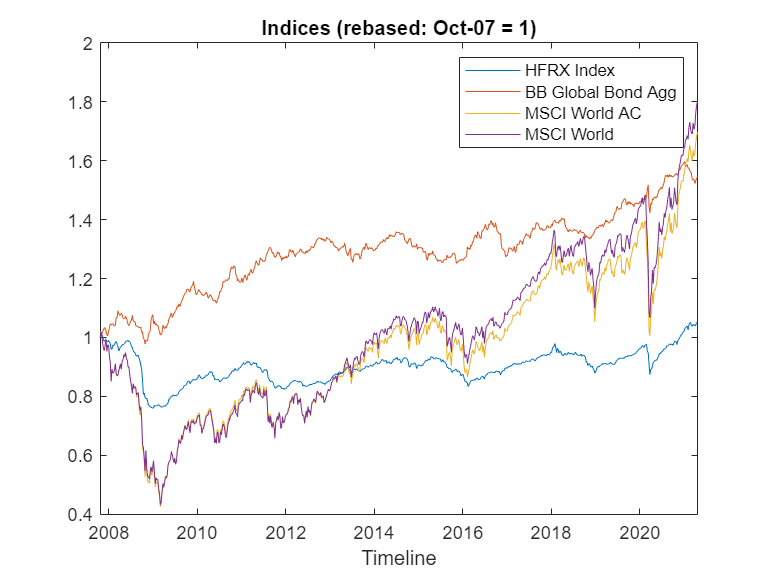

figure
plot(XTab.Date,XTab.HFRXGL/XTab.HFRXGL(1),'DisplayName','HFRX Index');
hold on;
plot(XTab.Date,XTab.LEGATRUU/XTab.LEGATRUU(1),'DisplayName','BB Global Bond Agg');
plot(XTab.Date,XTab.MXWD/XTab.MXWD(1),'DisplayName','MSCI World AC');
plot(XTab.Date,XTab.MXWO/XTab.MXWO(1),'DisplayName','MSCI World');
xlabel('Timeline')
title('Indices (rebased: Oct-07 = 1)')
legend
hold off;

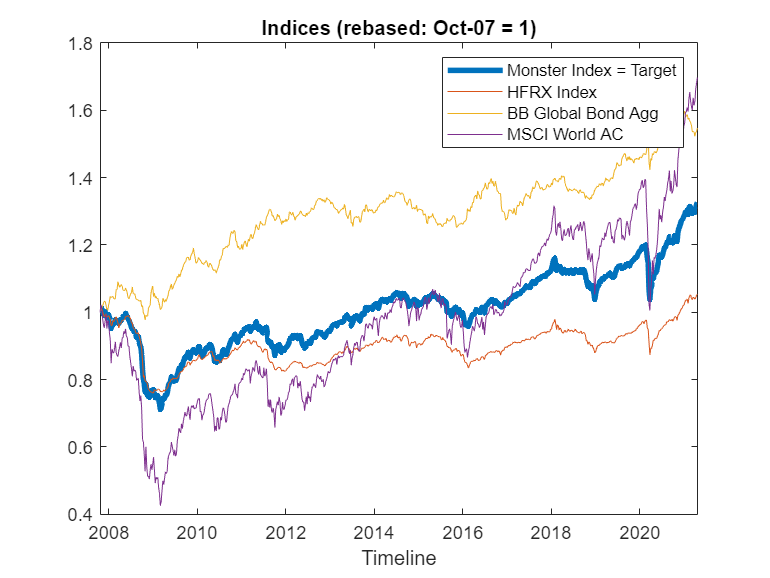

% Synthetic target weights
wHFRXGL = 0.5; 
wMXWO = 0.25;
wLEGATRUU = 0.25;

% Building the target
y = wHFRXGL*price2ret(HFRXGL) + wMXWO*price2ret(MXWO) + wLEGATRUU*price2ret(LEGATRUU); % "Monster Index" returns
target = (ret2price(y)); % "Monster Index" levels

figure
p = plot(XTab.Date,target,'DisplayName','Monster Index = Target');
p.LineWidth = 3;
hold on;
plot(XTab.Date,XTab.HFRXGL/XTab.HFRXGL(1),'DisplayName','HFRX Index');
hold on;
plot(XTab.Date,XTab.LEGATRUU/XTab.LEGATRUU(1),'DisplayName','BB Global Bond Agg');
plot(XTab.Date,XTab.MXWD/XTab.MXWD(1),'DisplayName','MSCI World AC');
xlabel('Timeline')
title('Indices (rebased: Oct-07 = 1)')
legend
hold off;

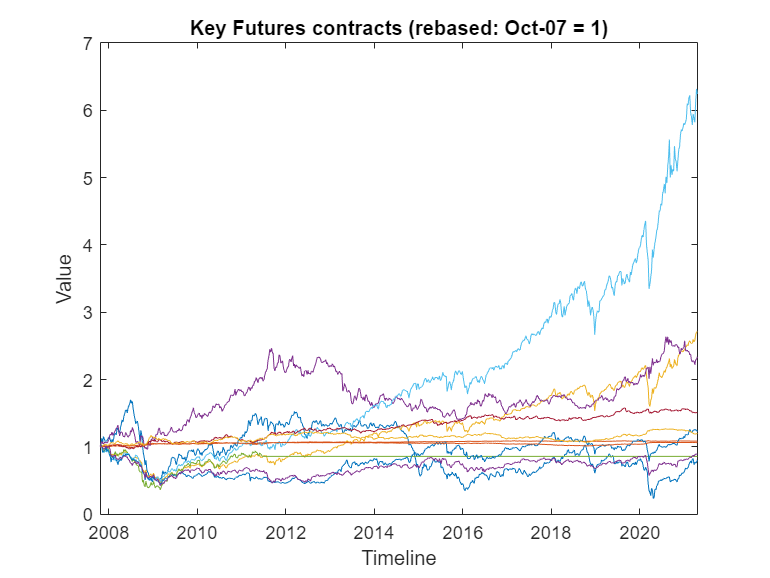

% Futures returns
X = [price2ret(CO1) price2ret(DU1) price2ret(ES1) price2ret(GC1)...
           price2ret(LLL1) price2ret(NQ1) price2ret(RX1) price2ret(TP1)...
           price2ret(TU2) price2ret(TY1) price2ret(VG1)];

figure
plot(XTab.Date, ret2price(X))
xlabel('Timeline')
ylabel('Value')
title('Key Futures contracts (rebased: Oct-07 = 1)')

rollingWindow = 150; % in weeks (52 = 1Y, 104 = 2Y...)

y_pred_Enet %load!!!!!!!!!!!!!!

y_pred_Enet =     0.9090
    0.9113
    0.9157
    0.9274
    0.9284
    0.9263
    0.9356
    0.9414
    0.9504
    0.9295


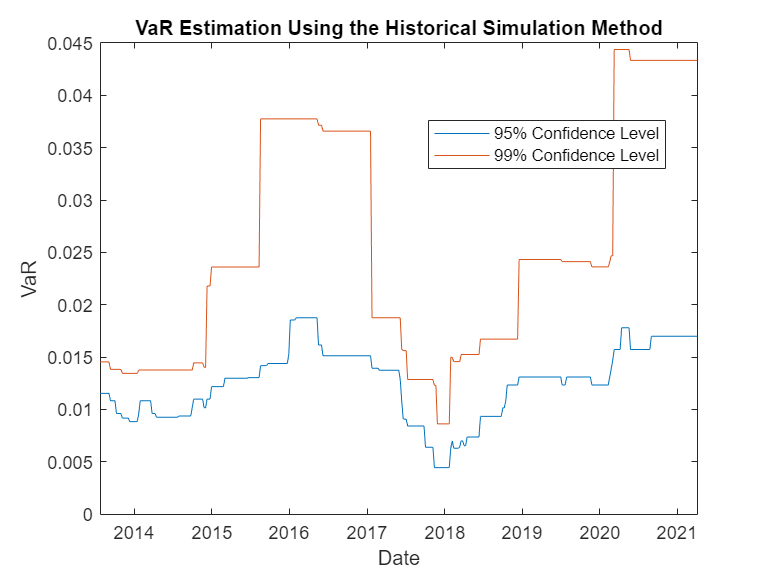

Returns = price2ret(y_pred_Enet);
DateReturns = Date(rollingWindow+1:end);
SampleSize = length(Returns);

TestWindowStart      = rollingWindow+1;
TestWindow           = TestWindowStart : SampleSize;
EstimationWindowSize = rollingWindow/2; %fare ricerca su dimensioni più adeguate

pVaR = [0.05 0.01];

Historical95 = zeros(length(TestWindow),1);
Historical99 = zeros(length(TestWindow),1);

for t = TestWindow
    i = t - TestWindowStart + 1;
    EstimationWindow = t-EstimationWindowSize:t-1;
    X = Returns(EstimationWindow);
    Historical95(i) = -quantile(X,pVaR(1)); 
    Historical99(i) = -quantile(X,pVaR(2)); 
end

figure;
plot(DateReturns(TestWindow),[Historical95 Historical99])
ylabel('VaR')
xlabel('Date')
legend({'95% Confidence Level','99% Confidence Level'},'Location','Best')
title('VaR Estimation Using the Historical Simulation Method')

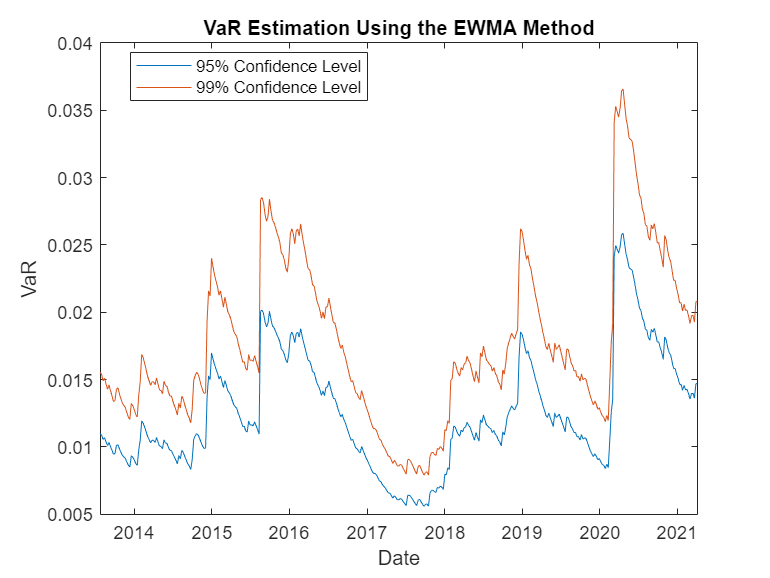

Lambda = 0.94; %frequently used in practice
Sigma2     = zeros(length(Returns),1);
Sigma2(1)  = Returns(1)^2;

for i = 2 : (TestWindowStart-1)
    Sigma2(i) = (1-Lambda) * Returns(i-1)^2 + Lambda * Sigma2(i-1); %extimation of the variance
end

Zscore = norminv(pVaR);
EWMA95 = zeros(length(TestWindow),1);
EWMA99 = zeros(length(TestWindow),1);

for t = TestWindow 
    k     = t - TestWindowStart + 1;
    Sigma2(t) = (1-Lambda) * Returns(t-1)^2 + Lambda * Sigma2(t-1);
    Sigma = sqrt(Sigma2(t));
    EWMA95(k) = -Zscore(1)*Sigma;
    EWMA99(k) = -Zscore(2)*Sigma;
end

figure;
plot(DateReturns(TestWindow),[EWMA95 EWMA99])
ylabel('VaR')
xlabel('Date')
legend({'95% Confidence Level','99% Confidence Level'},'Location','Best')
title('VaR Estimation Using the EWMA Method')

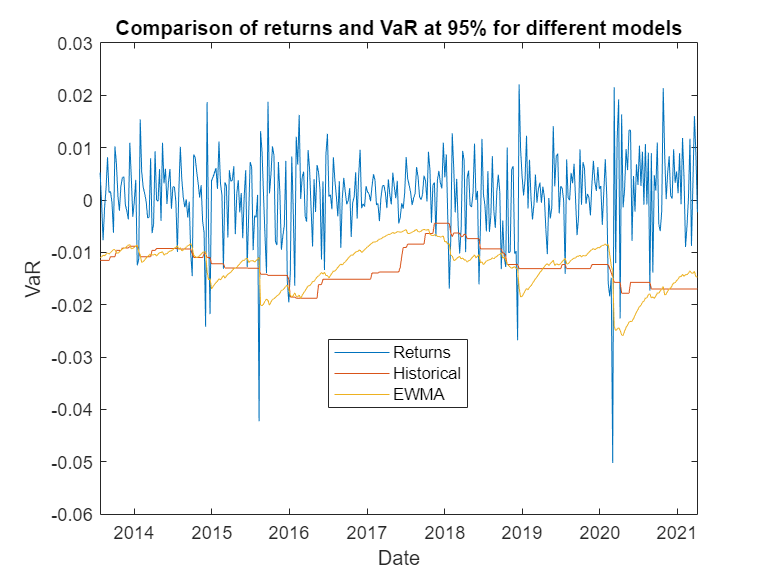

ReturnsTest = Returns(TestWindow);
DatesTest   = DateReturns(TestWindow);
figure;
plot(DatesTest,[ReturnsTest -Historical95 -EWMA95])
ylabel('VaR')
xlabel('Date')
legend({'Returns','Historical','EWMA'},'Location','Best')
title('Comparison of returns and VaR at 95% for different models')

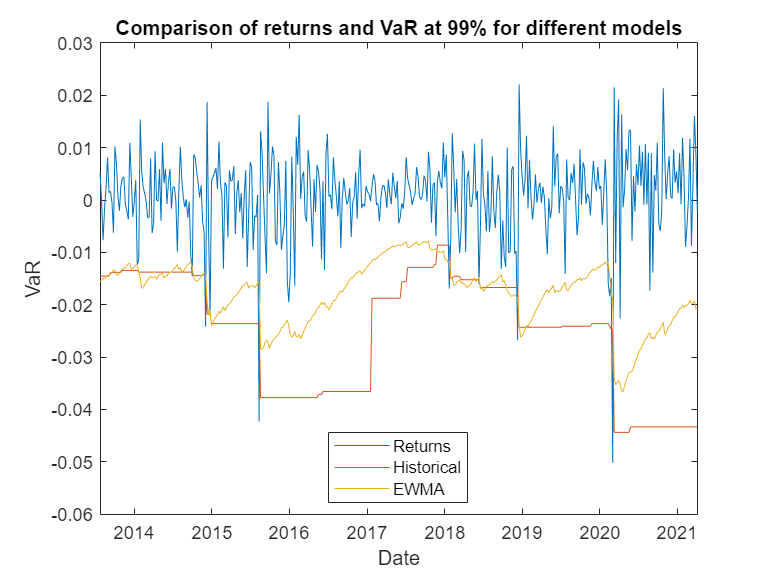

ReturnsTest = Returns(TestWindow);
DatesTest   = DateReturns(TestWindow);
figure;
plot(DatesTest,[ReturnsTest -Historical99 -EWMA99])
ylabel('VaR')
xlabel('Date')
legend({'Returns','Historical','EWMA'},'Location','Best')
title('Comparison of returns and VaR at 99% for different models')

vbt = varbacktest(ReturnsTest,[Historical95 EWMA95 Historical99 ...
    EWMA99],'PortfolioID','S&P','VaRID',{'Historical95','EWMA95',...
    'Historical99','EWMA99'},'VaRLevel',[0.95 0.95 0.99 0.99]);
runtests(vbt)

ans = 4×11 table
    PortfolioID        VaRID         VaRLevel      TL       Bin       POF       TUFF       CC       CCI       TBF       TBFI 
    ___________    ______________    ________    ______    ______    ______    ______    ______    ______    ______    ______

       "S&P"       "Historical95"      0.95      yellow    accept    accept    accept    reject    reject    reject    reject
       "S&P"       "EWMA95"            0.95      green     accept    accept    accept    reject    reject    reject    reject
       "S&P"       "Historical99"      0.99      yellow    reject    accept    accept    accept    accep